% scalar in front (for quaternions)

hoop1_pos = p_h4; % [3; 0; 2];
hoop1_unit = main_direction(u_h4); % [1; 0; 0];
hoop2_pos = p_h3; % [0; 3; 2];
hoop2_unit = main_direction(u_h3); % [0; 1; 0];
hoop3_pos = p_h2; % [-3; 0; 2];
hoop3_unit = main_direction(u_h2); % [1; 0; 0];
hoop4_pos = p_h1; % [0; -3; 2];
hoop4_unit = main_direction(u_h1); % [0; 1; 0];

box_distance = 0.5; % in meters
box_error = 0.1; % in meters

middle_point = [mean([hoop1_pos(1), hoop2_pos(1), hoop3_pos(1), hoop4_pos(1)]), mean([hoop1_pos(2), hoop2_pos(2), hoop3_pos(2), hoop4_pos(2)])];


% WAYPOINTS

%knots = [0 5 (7) 9 14 (16) 18 23 (25) 27 32 (34) 36 41];
knots = 7*[0 1 2 3 4 5];
waypoints = cell(1,6);
waypoints{1} = [middle_point(1) ; middle_point(2) ; 1]; % start 
waypoints{2} = hoop1_pos;
waypoints{3} = hoop2_pos;
waypoints{4} = hoop3_pos;
waypoints{5} = hoop4_pos;
waypoints{6} = [middle_point(1) ; middle_point(2) ; 0.3];   %e nd

waypoints_vel = [0 0 0; hoop1_unit'; hoop2_unit'; hoop3_unit'; hoop4_unit'; 0 0 0]'.*0.5;

corridors.times = [];
corridors.x_lower = [];
corridors.x_upper = [];
corridors.y_lower = [];
corridors.y_upper = [];
corridors.z_lower = [];
corridors.z_upper = [];

order = 7;
make_plots = true;

Optimization will be performed on end derivatives. This will improve optimization performance.
solving 1 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 2 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
solving 3 th dimension..



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>
success! 
Done!
Elapsed time is 0.070796 seconds.


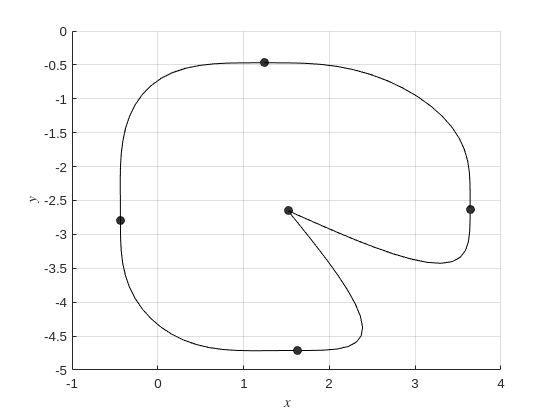

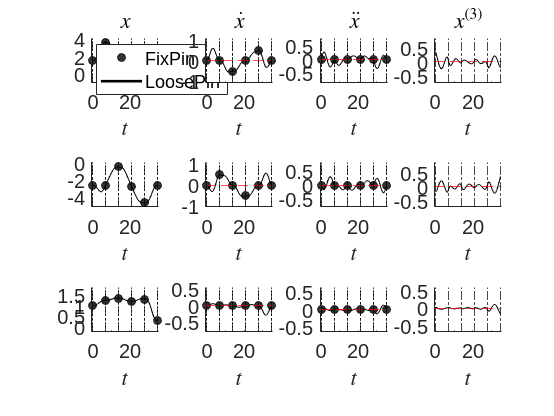

clf
poly_traj = uas_minimum_snap_v2(knots, order, waypoints, corridors, make_plots, waypoints_vel);

function direction = main_direction(unit_vec)
    maximum = max(abs(unit_vec));
    if abs(unit_vec(1)) == maximum
        direction = [1; 0; 0]*unit_vec(1)/abs(unit_vec(1));
    elseif abs(unit_vec(2)) == maximum
        direction = [0; 1; 0]*unit_vec(2)/abs(unit_vec(2));
    elseif abs(unit_vec(3)) == maximum
        direction = [0; 0; 1]*unit_vec(3)/abs(unit_vec(3));
    else
        direction = unit_vec;
    end
end